% 定义变量范围
D = linspace(0, 0.5, 100);  % D 的范围从 0 到 0.5
phi = linspace(0, 0.99, 100);  % phi 的范围从 0 到 1

% 创建网格
[D_grid, phi_grid] = meshgrid(D, phi);

% 预分配 M 的矩阵
M = zeros(size(D_grid));

% 计算不同情况下 M 的值
for i = 1:length(phi)
    for j = 1:length(D)
        % 获取当前的 D 和 phi
        D_val = D(j);
        phi_val = phi(i);
        
        % 根据不同的条件计算 M
        if (0 <= phi_val) && (phi_val < 0.5 - D_val)
            M(i,j) = 2*D_val;
        elseif (0.5 - D_val <= phi_val) && (phi_val < 0.5)
            M(i,j) = -(-2 + 4*phi_val + 2*D_val);
        elseif (0.5 <= phi_val) && (phi_val < 1 - D_val)
            M(i,j) =  -2*D_val ;
        elseif (1 - D_val <= phi_val) && (phi_val < 1)
            M(i,j) =2*D_val+ 4*phi_val - 4;
        end
    end
end

% % 限制 M 的范围在 0 到 2 之间
 M(M < 0) = 0;
% M(M > 2) = 2;

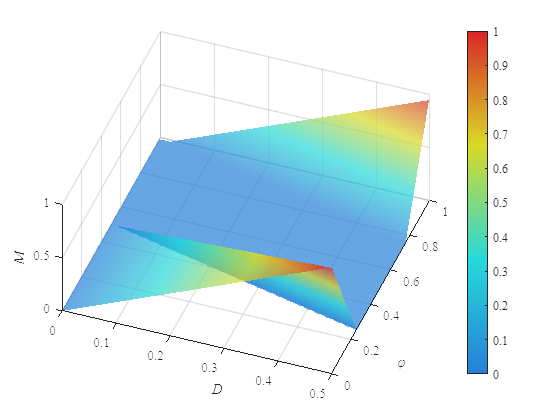

% 绘制3D图
figure;
surf(D_grid, phi_grid, M,'FaceAlpha', 0.7);

% 禁用边框线
set(gca, 'FontName', 'Times New Roman');
%set(gca, 'EdgeColor', 'none'); % 这行可以去掉曲面连接线

% 设置颜色映射
n = 256; % 定义颜色分辨率
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度
colormap(desaturated_cmap);
colorbar;

% 平滑显示
shading interp;  % 平滑插值

% 设置视角和网格
view(20,60); % 设置视角
grid on;
hold on;
% 添加标题和标签
xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('\it{M}');
zlim([0,1])

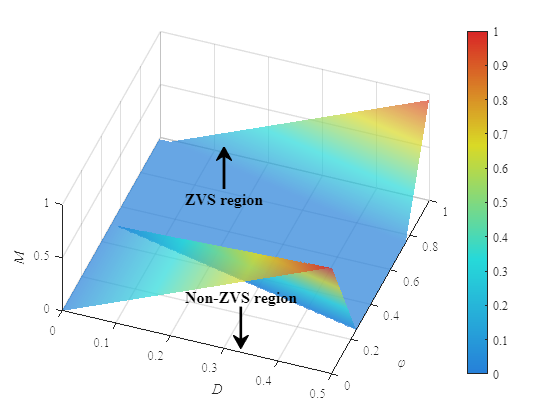


% 箭头
%annotation('arrow', [0.43, 0.43], [0.21, 0.11], 'Color', 'black', 'LineWidth', 2);
% 箭头
%annotation('arrow', [0.4, 0.4], [0.55, 0.65], 'Color', 'black', 'LineWidth', 2);
annotation('textarrow', [0.43, 0.43], [0.27, 0.17], 'String', 'Non-ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', ...
    'FontWeight', 'bold', 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);

annotation('textarrow', [0.4, 0.4], [0.55, 0.65], 'String', 'ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', ...
    'FontWeight', 'bold', 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);

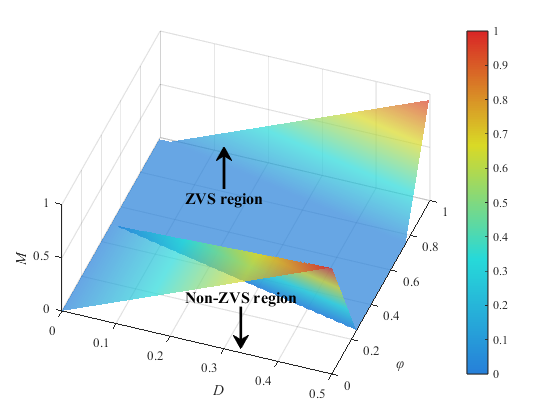

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'ZVSHighVoltageSide.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');